% Adjusting the image contrast 
gray = imread('dark3.jpg')

gray = 1600×2560×3 uint8 배열
gray(:,:,1) =

  1 ~ 1,666번 열

     0     0     0     0     1     1     1     1     0     0     0     0     1     1     1     1     0     6     0     0     0     1     0     0     0     0     0     1     4     5     5     6     3     2     1     0     0     1     2     3     5     3     3     6     7     4     3     6     3     2     1     0     0     0     0     0     1     1     1     1     1     1     1     2     1     1     4     5     4     5     7     6     0     0     0     0     0     0     0     2     2     0     0     3     0     0     0     0     1     1     2     3     3     3     4     4     5     0    10     2     2     4    36   156   235   100     8     0     0     0     1     0     0     0     0     0     1     1     1     0     1     1     1     0     0     0     0     0     1     0     0     0     0     0     0     0     2     2     5     6     5     0     0     0     0     3     3     0     0     1     2     0     1     3     1     3    1

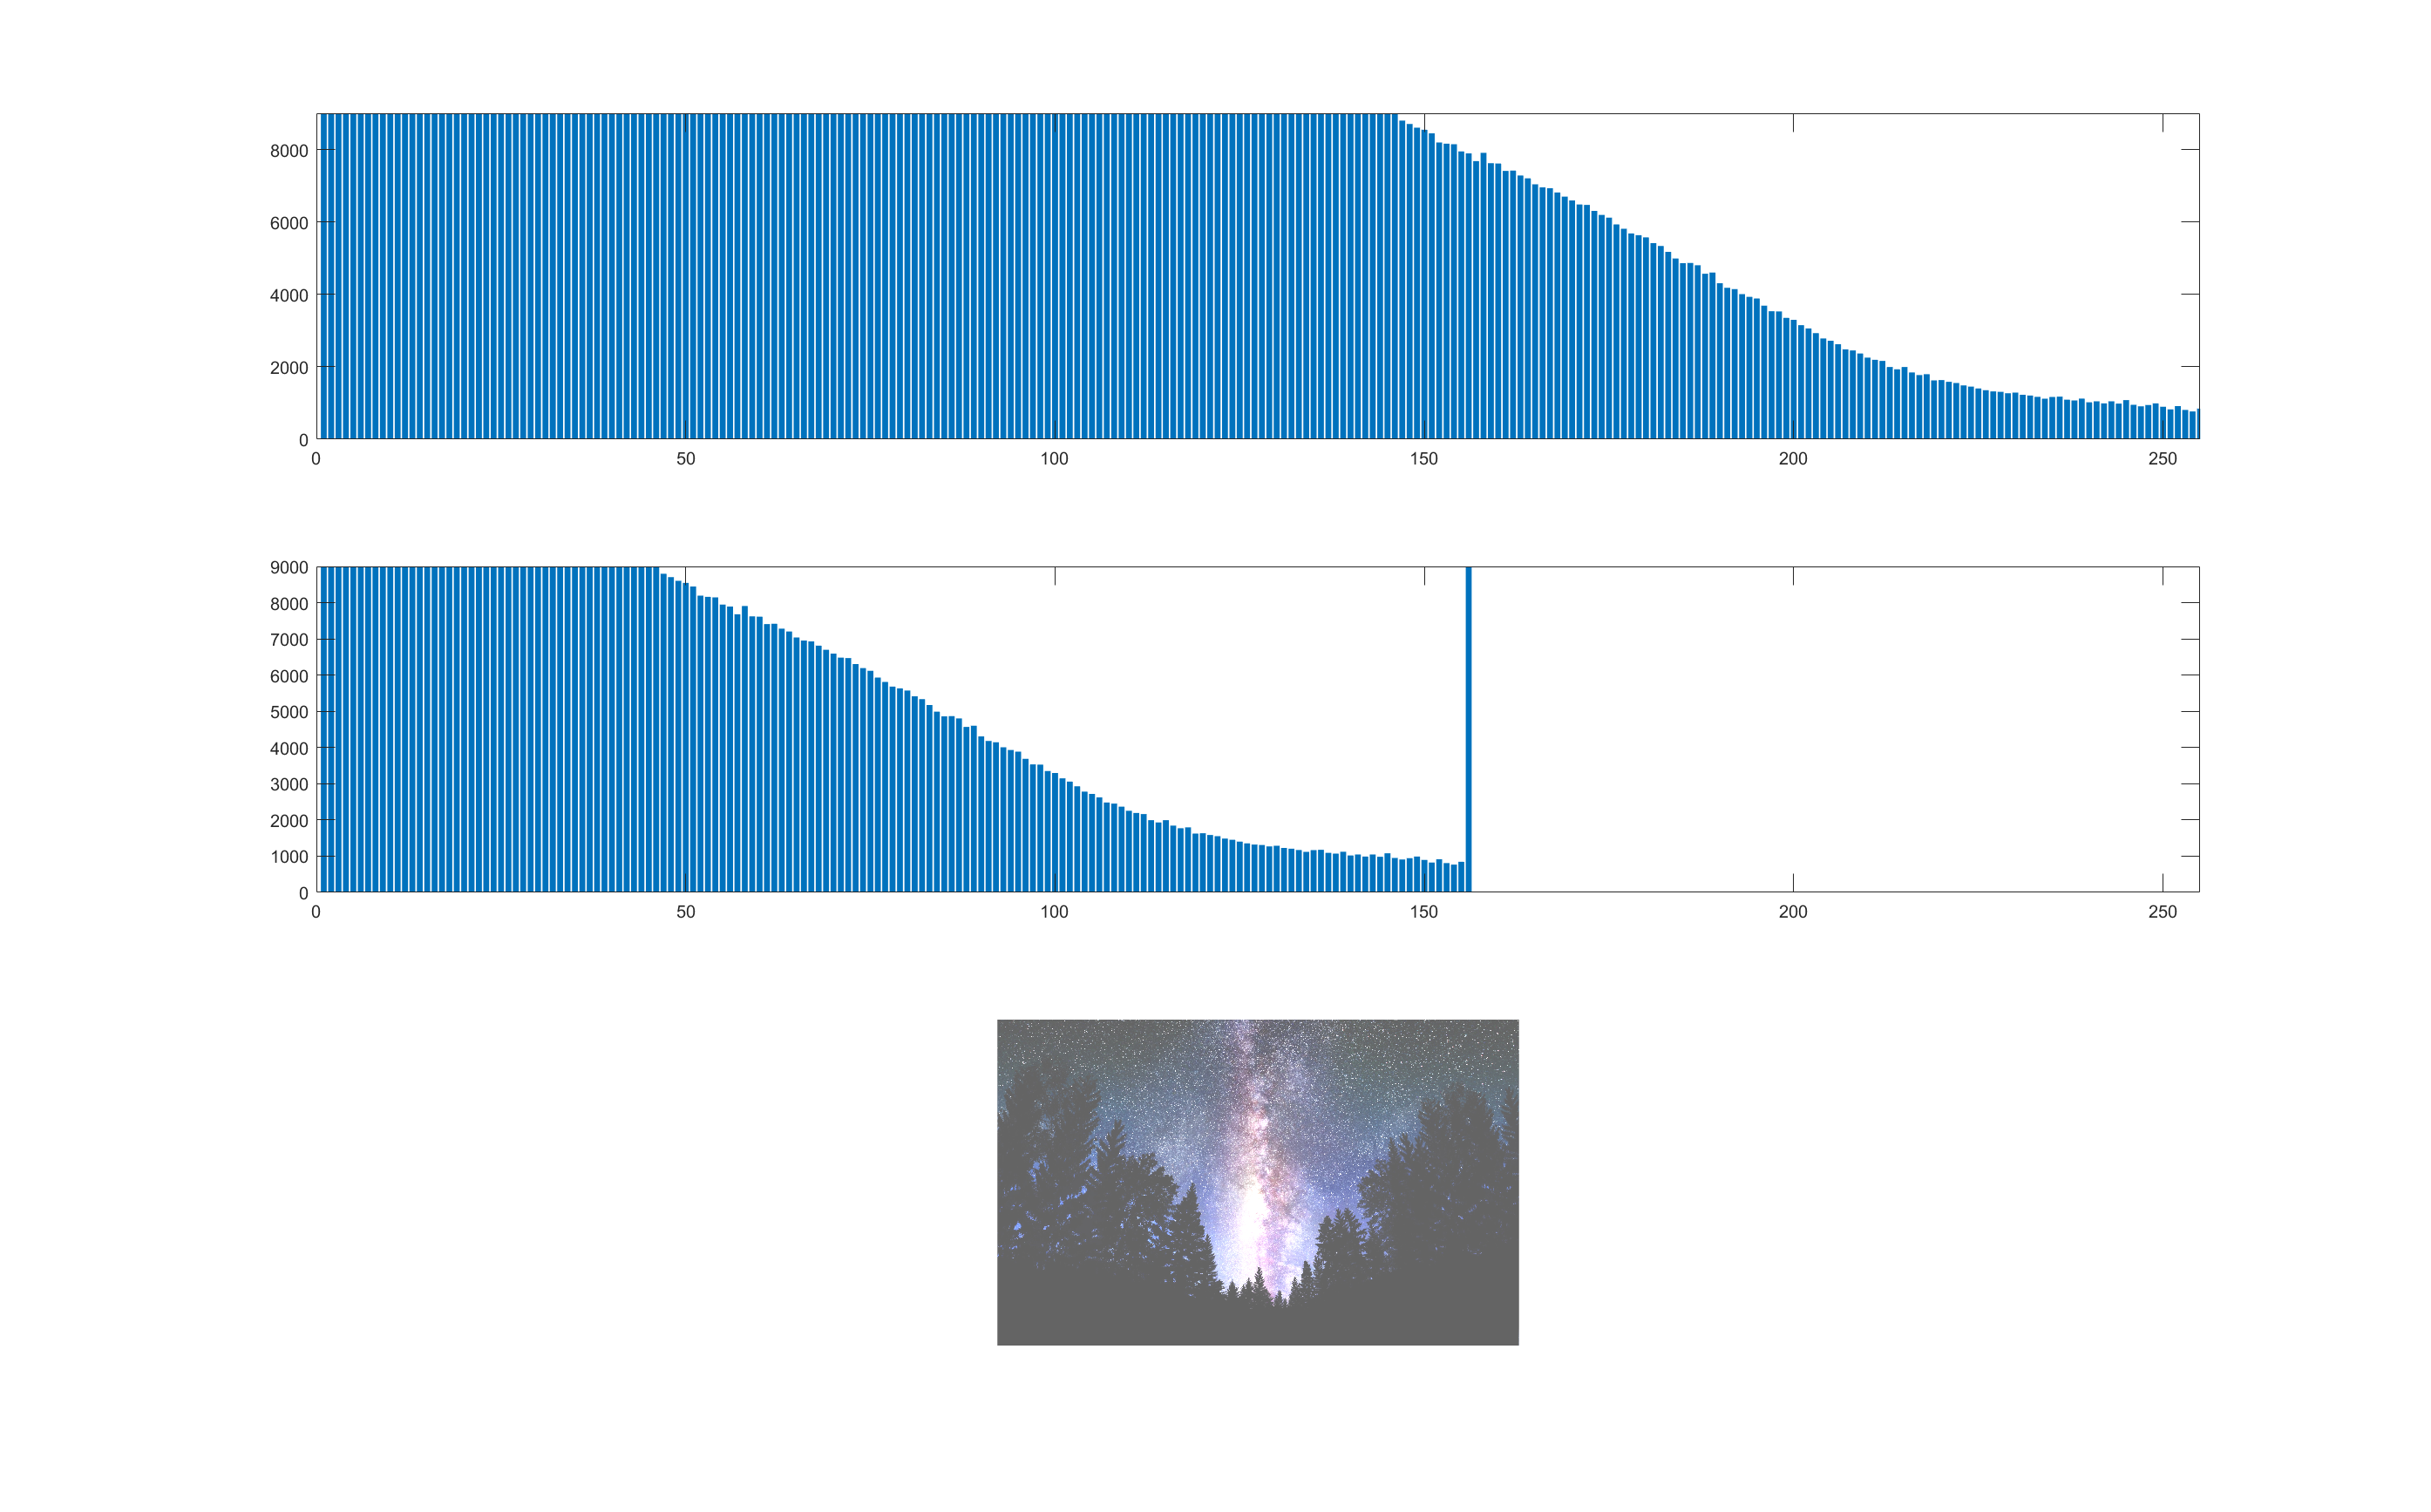

imshow(gray)

darker = gray - 100;
brighter = gray + 100;

figure(1)
imshow(darker)

figure(2)
imshow(brighter)

% Getting the histogram of images
% imhist is function that stores the array of 1-dimension from histogram of image
histogram0 = imhist(gray); 
histogram1 = imhist(darker);
histogram2 = imhist(brighter);

% Plotting the images
subplot(3, 1, 1)
bar(histogram0)
xlim([0 255])
ylim([0 9000])

subplot(3, 1, 2)
bar(histogram1)
xlim([0 255])
ylim([0 9000])

subplot(3, 1, 3)
bar(histogram2)
xlim([0 255])
ylim([0 9000])

histogram_equlization = histeq(darker);

figure(1)
imshow(darker)

figure(2)
imshow(histogram_equlization)

figure(3)
imshow(gray)